# Tactile Time Series Encoding with Fourier Basis Expansion and Higher Orthogonal Iteration of Tensors

## Prepare Dataset

Load the files **fc1.mat **and** fc2.mat **that contain the data structs.

fc1 = load('fc1.mat'); % For classification and analysis
% fc2 = load('fc2.mat'); % For verification on new classes

## Set Hyper-Parameters for Processing

- hiddenlayer_size - Size of hidden layer for ANN classifier

- n1_range - Range of PC1 dimensions

- ncores - Dimensions of truncation of 3 modes 

- num_neighbors - Number of neighboring points for kNN

- repitions - Number of repititions to calculate average classification accuracy

- voption - Option for velocity groups (1 for positive, 0 for all, -1 for negative)

- classifier_name - Names of classifiers for comparison

% hiddenlayer_size = 20;
n1_range = 3:10;
n_cores = [3, 1, 0];
num_neighbors = 10;
repitions = 3;% more than 1
perc = 0.5;
voption = 0;
% classifier_name = {'Classification Tree', 'Naive Bayes', 'kNN', 'Weighted kNN', 'Neural Network'};
classifier_name = {'Classification Tree', 'Naive Bayes', 'kNN', 'Weighted kNN'};

## Encode Samples and Classify in Latent Space

The process requires [tensor_toolbox](https://www.tensortoolbox.org/) to be included in the path.

**fbasis_coeffs** as the dataset is represented as a 3D coefficient matrix C computed via basis expansion from the original collection of tactile responses.

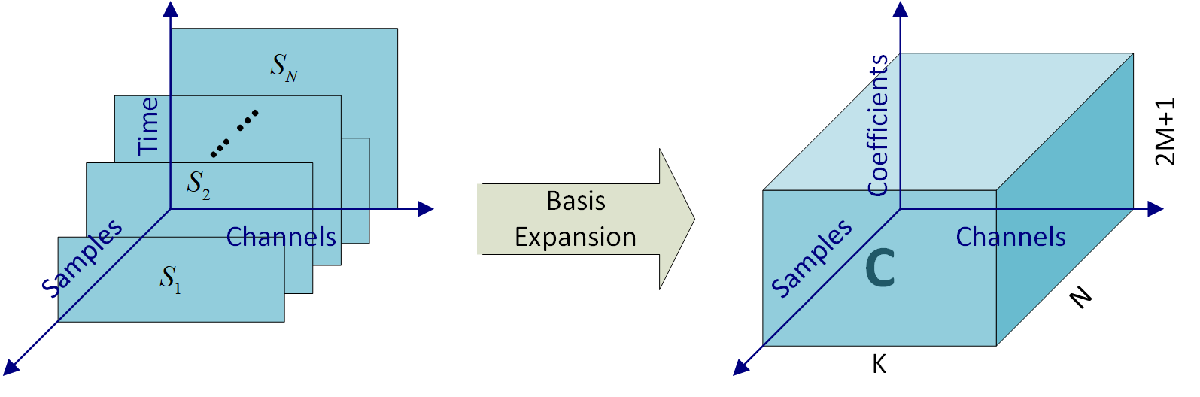

The original collection of tactile responses $\mathbf{S}$ contains     $N$samples, each of which is a matrix $S_{i} \in \mathcal{N}^{T_{i} \times K}$where $T_{i}$ is the length of the time sequence and $K$is the number of sampling channels. To align the samples of different length and apply analysis in frequency domain, the time sequences are transformed to Fourier basis representations by $S_{i}(t) \approx \sum_{m=1}^{2M+1}c_{m}\phi_{m} = C_{i}^{T}\Phi(t)$, where $C_i \in R^{K\times \left(2M+1\right)}$ is the coefficient matrix, $\Phi \left(t\right)={\left\lbrack \phi_1 \left(t\right),\phi_2 \left(t\right),\ldotp \ldotp \ldotp ,\phi_{2M+1} \left(t\right)\right\rbrack }^T$ is the vector of basis functions and $2M+1$ is the number of basis. The Fourier basis functions are $1, \sin{\omega t}, \cos{\omega t}, \sin{2\omega t}, \cos{2\omega t}, ..., \sin{M\omega t}, \cos{M\omega t}$, where $\omega = \frac{2\pi}{P}$ definesthe period $P
$ of oscillation of the first trigonometric function pair. For each coefficient matrix $C_i$ the covariance matrix is computed and all covariance matrices are stacked along the third direction to obtain a covariance tensor $\mathbf{Cov} \in \mathcal{R}^{K \times K \times N}$.

**Higher orthogonal iterationof tensors (HOOI) **[1][2] decomposes the original covariance tensor into a core tensor $\mathbf{S}$ in lower dimensions and factor matrices with best approximation in terms of Frobenius loss. The original tensor can be reconstructed as $\mathbf{Cov} = \mathbf{S} \times_{1} U_{1} \times_{2} U_{2} \times_{3} U_{3}$ where $\times_{i}$ is a mode-$i$ product (tensor matrix multiplication).

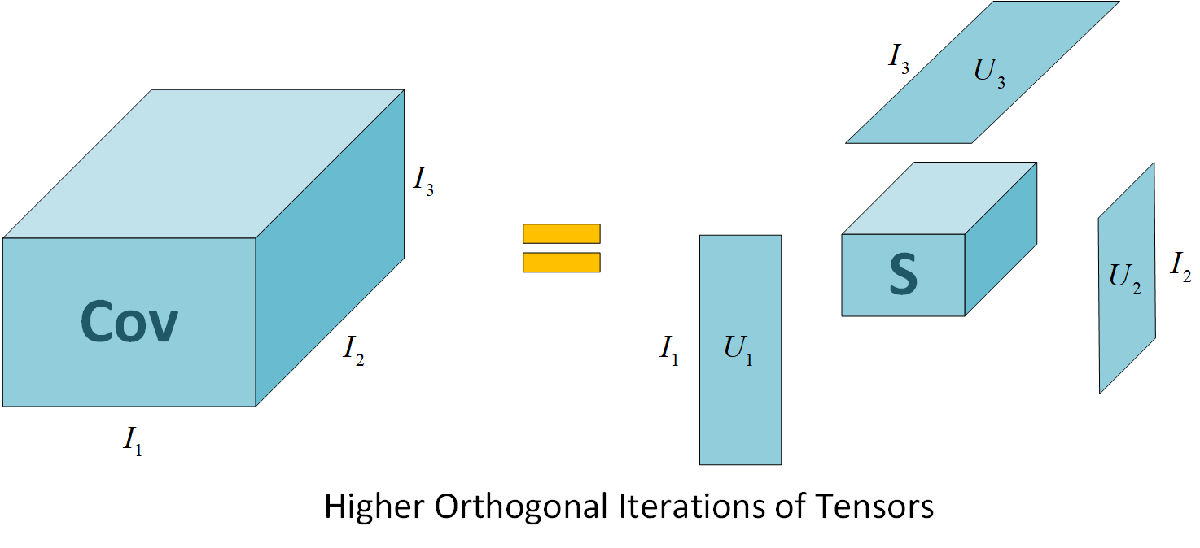

Columns of factor matrices $U_1$, $U_2$ and $U_3$ are the left singular vectors correspondent to singular values in descending orders with respect to the **SVD** of mode-$i$ unfolding; by selecting the desired number of eigenvectors, a compressed representation of the original data can be computed by $\mathbf{L} = \mathbf{Cov} \times_{1} U_{1}(1:n_{1}, :) \times_{2} U_{2}(1:n_{2}, :)$ as the 3rd direction compresses the samples, which is not expected, $U_3$ is not used. Depends on the selection of $n_1$ and $n_2$, $\mathbf{L}$ can be a 1D, 2D or 3D tensor. For easier visualization, this process considers $n_1 =$ 3 and $n_2 =1$ which leads to a latent matrix $\mathbf{L} \in \mathcal{R}^{N \times 3}$.  

#### References

- Haiping Lu, K. N. Plataniotis, and A. N. Venetsanopoulos, ‘MPCA: Multilinear Principal Component Analysis of Tensor Objects’, *IEEE Trans. Neural Netw.*, vol. 19, no. 1, pp. 18–39, Jan. 2008, doi: [10.1109/TNN.2007.901277](https://doi.org/10.1109/TNN.2007.901277).  

- A. Zare, A. Ozdemir, M. A. Iwen, and S. Aviyente, ‘Extension of PCA to Higher Order Data Structures: An Introduction to Tensors, Tensor Decompositions, and Tensor PCA’, *arXiv:1803.00704 [eess]*, Jun. 2018, Accessed: Feb. 06, 2020. [Online]. Available: [http://arxiv.org/abs/1803.00704](http://arxiv.org/abs/1803.00704).  

clear classifier net
rates = zeros(repitions, numel(n1_range), numel(classifier_name));
for i = 1:numel(n1_range)
    ncores = [n1_range(i), 1, 0];
    for j = 1:repitions
        [~, Z, Zt, train_labels, test_labels] = tacProcess(fc1, ncores, voption, perc);
        % Classical classifiers
        classifier{1} = fitctree(Z, train_labels(:, 1));
        classifier{2} = fitcnb(Z, train_labels(:, 1), 'DistributionNames', 'kernel');
        classifier{3} = fitcknn(Z, train_labels(:, 1), 'NumNeighbors', 10);
        classifier{4} = fitcknn(Z, train_labels(:, 1), 'NumNeighbors', 10, 'DistanceWeight', 'squaredinverse');
        % Neural network classifier
%         net = patternnet(hiddenlayer_size);
%         net.divideParam.trainRatio = 80/100;
%         net.divideParam.valRatio = 20/100;
%         inputs = Z';
%         targets = zeros(max(train_labels(:, 1)), length(Z'));
%         for l = 1:length(train_labels)
%             targets(train_labels(l, 1), l) = 1;
%         end
%         [net, tr] = train(net,inputs,targets);
%         classifier{5} = net;
        
        for k = 1:numel(classifier)
            y = predict(classifier{k}, Z);
            yt = predict(classifier{k}, Zt);
            rates(j, i, k) = (sum(y == train_labels(:, 1)) + sum(yt == test_labels(:, 1)))/(length(train_labels(:, 1)) + length(test_labels(:, 1)));
        end
%         [~, y] = max(net(Z'));
%         [~, yt] = max(net(Zt'));
%         rates(j, i, end) = (sum(y' == train_labels(:, 1)) + sum(yt' == test_labels(:, 1)))/(length(train_labels(:, 1)) + length(test_labels(:, 1)));
    end
end

  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.
  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors fo

Classification results are compared in the 3D latent space with multiple classifiers. Classifiers are trained on training set and tested on both training set and test set. In the latent space, data sampled at **various sliding velocities **and** pressures** are grouped together to show the clustering capability of the proposed data embedding structure. Best results are achieved with **weighted kNN** with **10 neighbors** and **squared inverse distance weighting**.

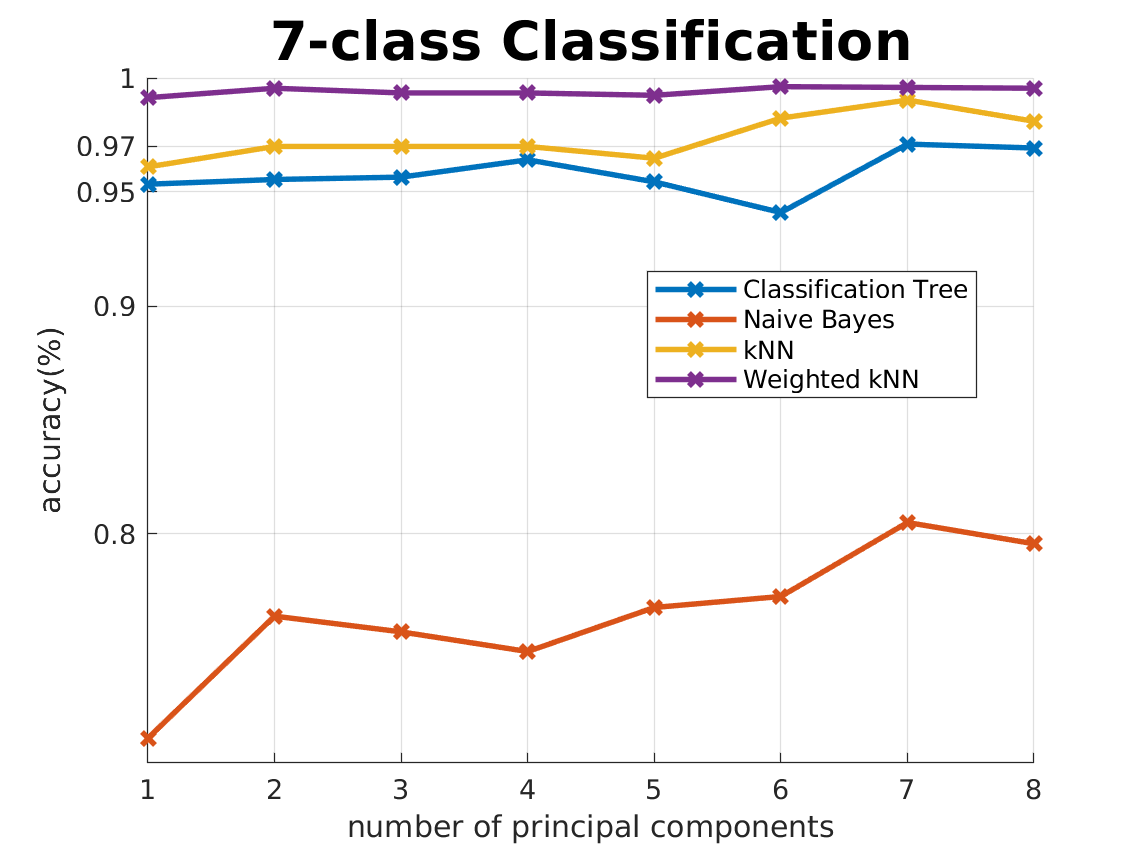

close all

%% Classification statistics
h(1) = figure(1);
hold on
title('7-class Classification', 'FontSize', 20)
xlabel('number of principal components')
ylabel('accuracy(%)')
avg_rates = squeeze(mean(rates, 1));
plot(avg_rates, 'LineWidth', 2, 'Marker', 'x');
yticks([0.5 0.7 0.8 0.9 0.95 0.97 1])
grid on
legend(classifier_name, 'Location', 'best')

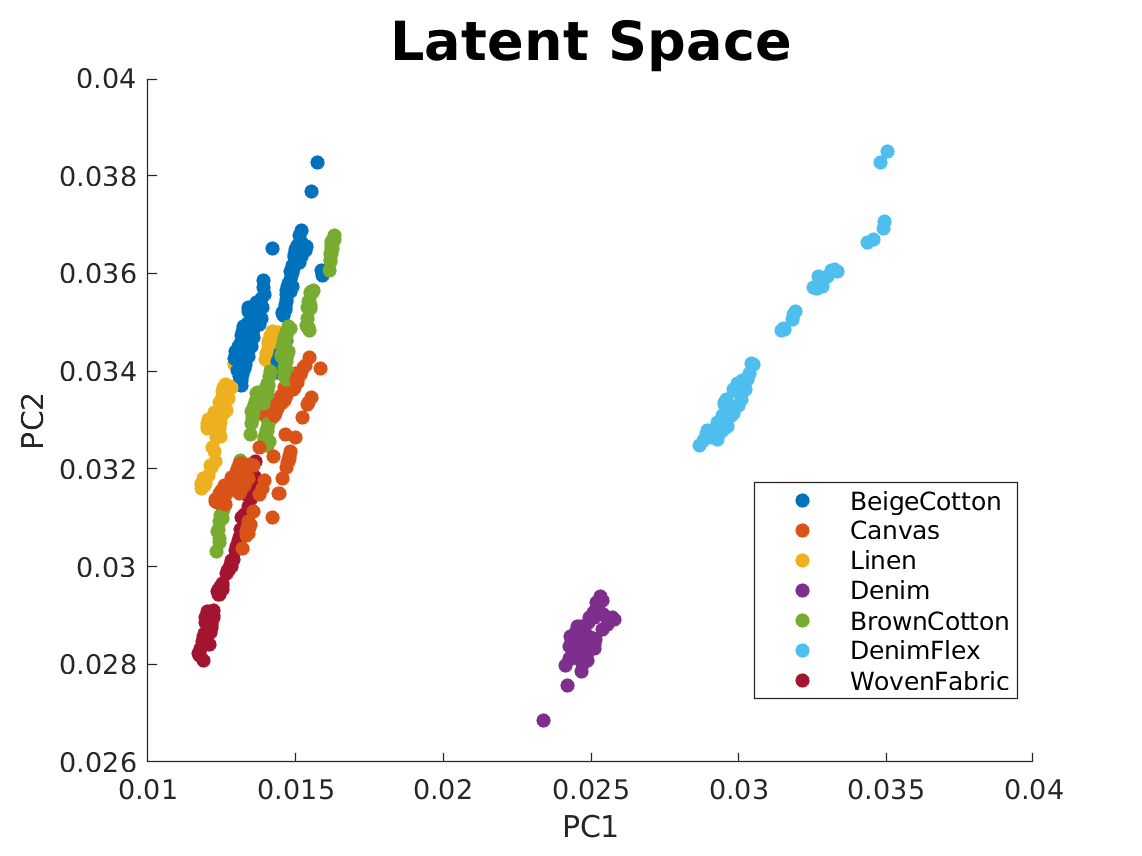

%% 3D latent space
h(2) = figure(2);
hold on
title('Latent Space', 'FontSize', 20)
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
Zp = [Z; Zt];
M = containers.Map(fc1.class_ids, string(fc1.class_names).strip('both'));
func = @(i) string(M(i));
labels = arrayfun(func, [train_labels(:, 1); test_labels(:, 1)]);
gscatter3(Zp(:, 1),  Zp(:, 2),  Zp(:, 3), labels(:, 1));
legend('Location', 'best')
view([0 90])

## Latent Space Analysis and 3D Visualization

tic
[T, Z, Zt, train_labels, test_labels] = tacProcess(fc1, n_cores, voption, perc);

  Computing 1 leading e-vectors for factor 2.
  Computing 0 leading e-vectors for factor 3.


toc

Elapsed time is 0.028649 seconds.


classifier = fitcknn(Z, train_labels(:, 1), ...
    'Distance', 'Euclidean', ...
    'NumNeighbors', num_neighbors, ...
    'DistanceWeight', 'SquaredInverse');
y = classifier.predict(Z);
yt = classifier.predict(Zt);

### Plot confusion matrix

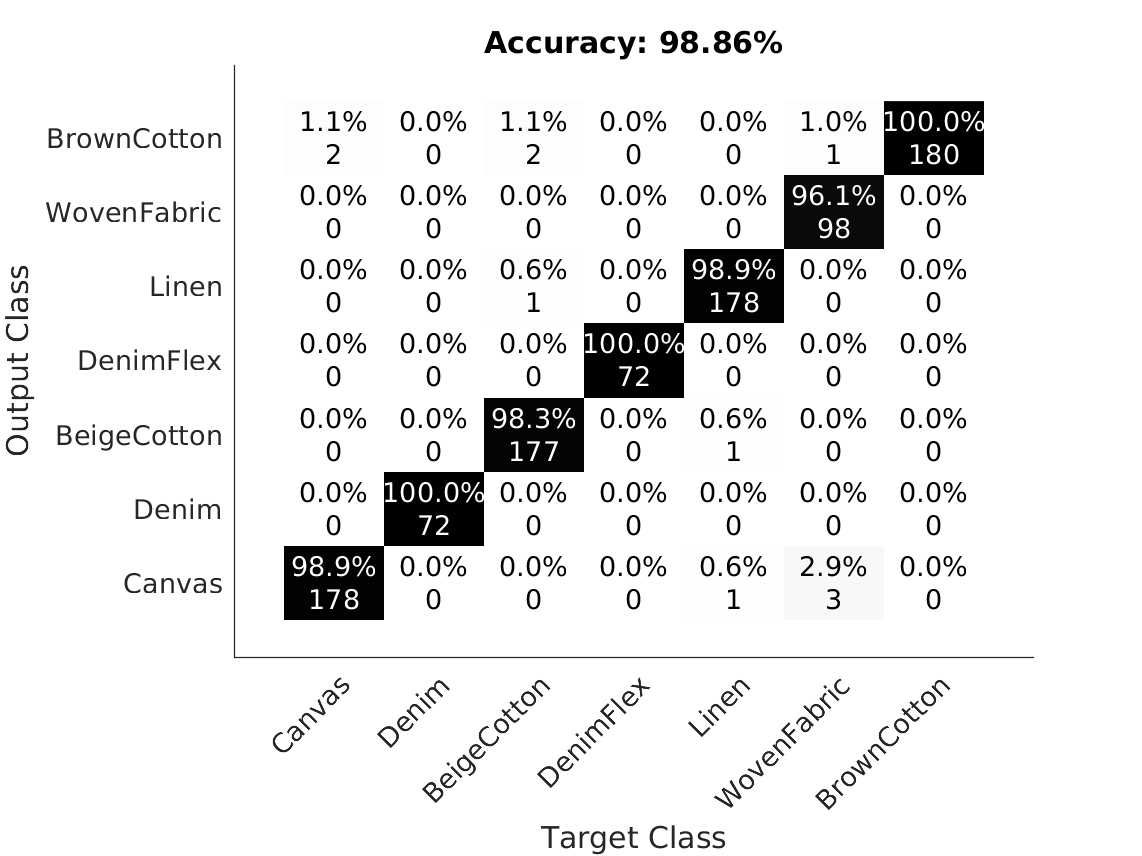

h(3) = figure(3);
hold on
cm = confusionmat([y; yt], [train_labels(:, 1); test_labels(:, 1)], 'Order', 1:7);
plotConfMat(cm, arrayfun(func, 1:7));
xtickangle(45)

### Visualize in pressure groups

In the latent space plot, data sampled at **the same pressures** are dyed with **the same colors**. Due to the over-elasticity of the two denims, sliding-up experiments were not carried out for Denim and DenimFlex with the current setup. Negative velocities imply a downward sliding direction during the experiments.

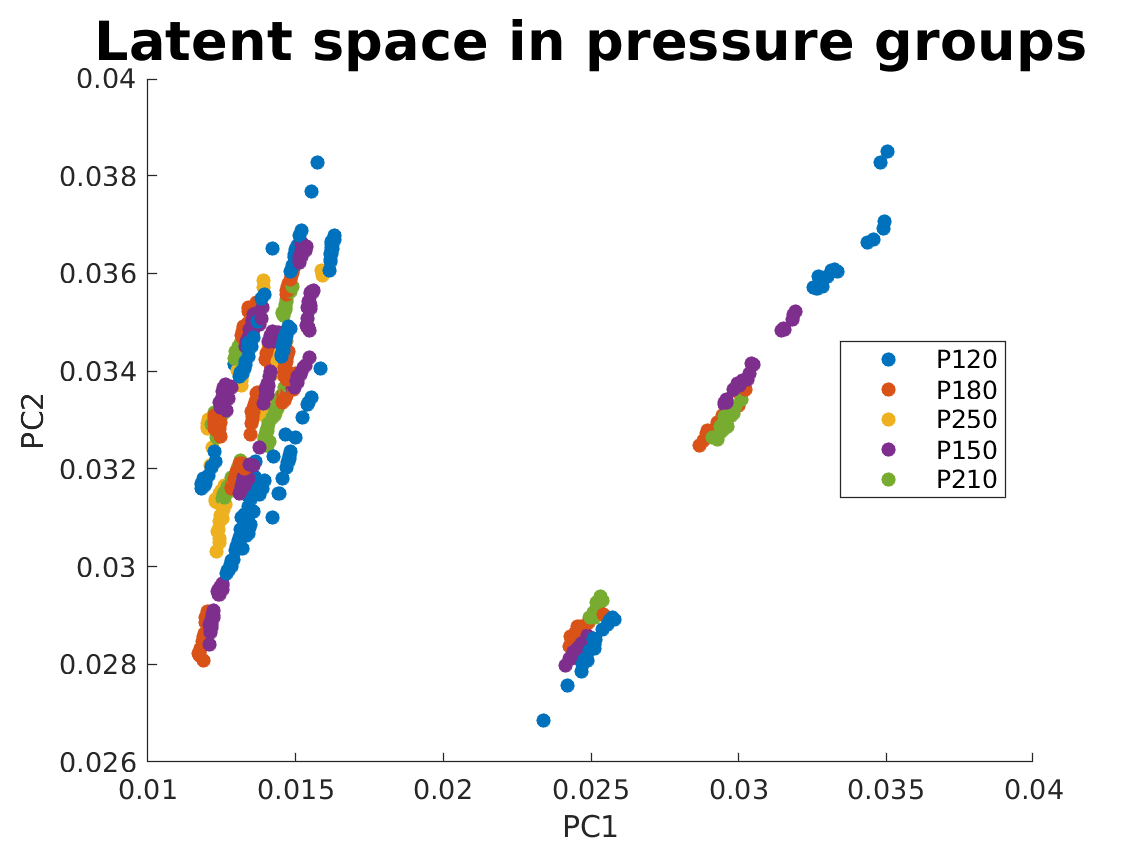

Zp = [Z; Zt];
all_labels = [train_labels; test_labels];

h(4) = figure(4);
hold on
title('Latent space in pressure groups', 'FontSize', 20)
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
gscatter3(Zp(:, 1), Zp(:, 2), Zp(:, 3), "P"+all_labels(:, 2));
view([0, 90])

### Visualize in velocity groups

In the latent space plot, data sampled at **the same velocities** are dyed with **the same colors**.

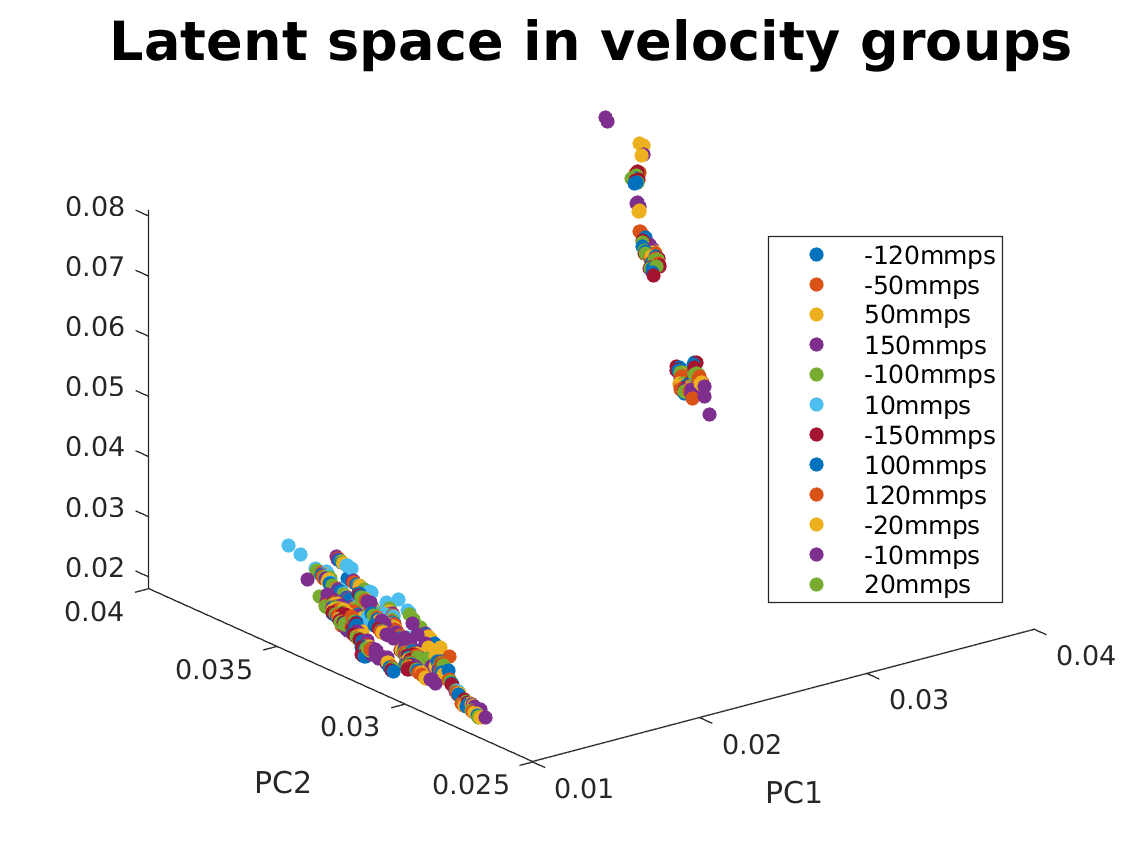

h(5) = figure(5);
hold on
title('Latent space in velocity groups', 'FontSize', 20)
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
gscatter3(Zp(:, 1), Zp(:, 2), Zp(:, 3), all_labels(:, 3)+"mmps");

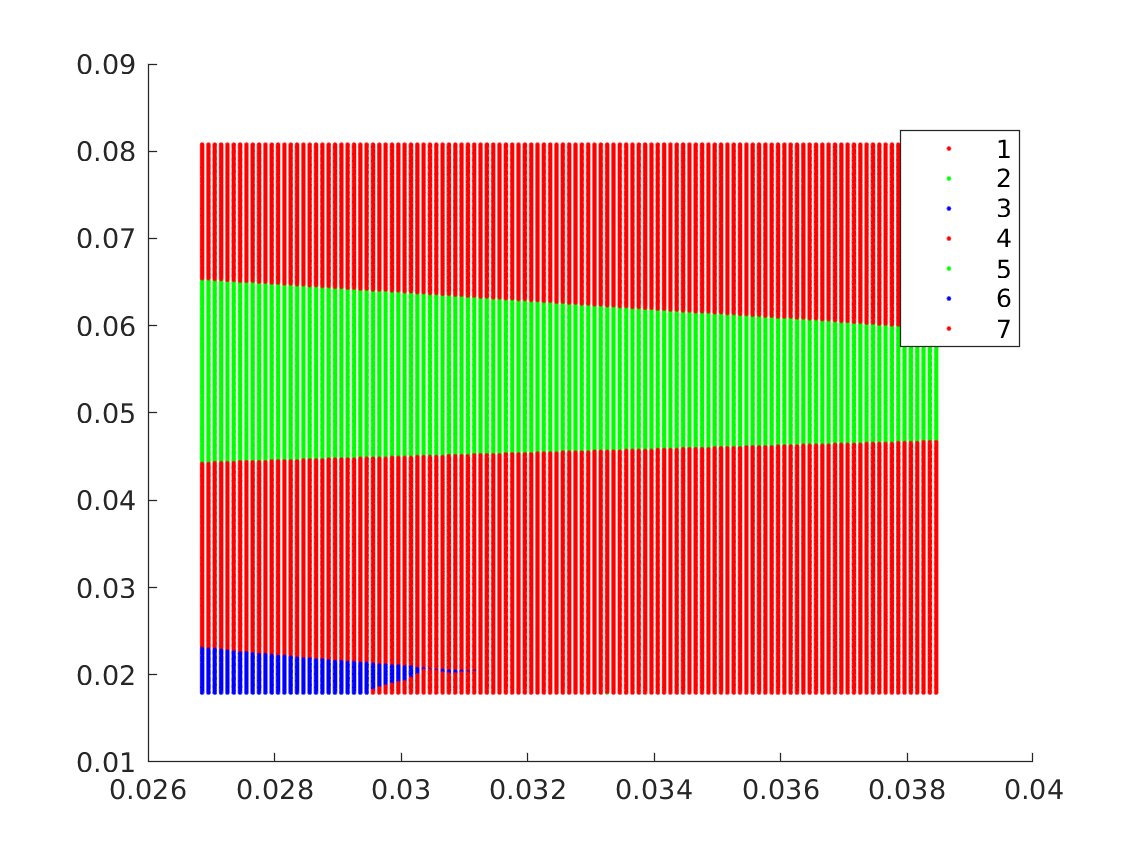

h(6) = figure(6);
hold on

x1range = min(Zp(:,1)):.0001:max(Zp(:,1));
x2range = min(Zp(:,2)):.0001:max(Zp(:,2));
x3range = min(Zp(:,3)):.0001:max(Zp(:,3));
[xx1, xx2, xx3] = meshgrid(x1range,x2range,x3range);
XGrid = [xx1(:) xx2(:) xx3(:)];
predictedspecies = predict(classifier, XGrid);

gscatter3(xx1(:), xx2(:), xx3(:), predictedspecies,'cmyk');

## Encoding New Dataset with Trained Encoder

Try encoding new dataset containing samples of unknown classes with the factor matrices obtained from **HOOI **on training set. Visualize the encoded new samples in the original 3D latent space.

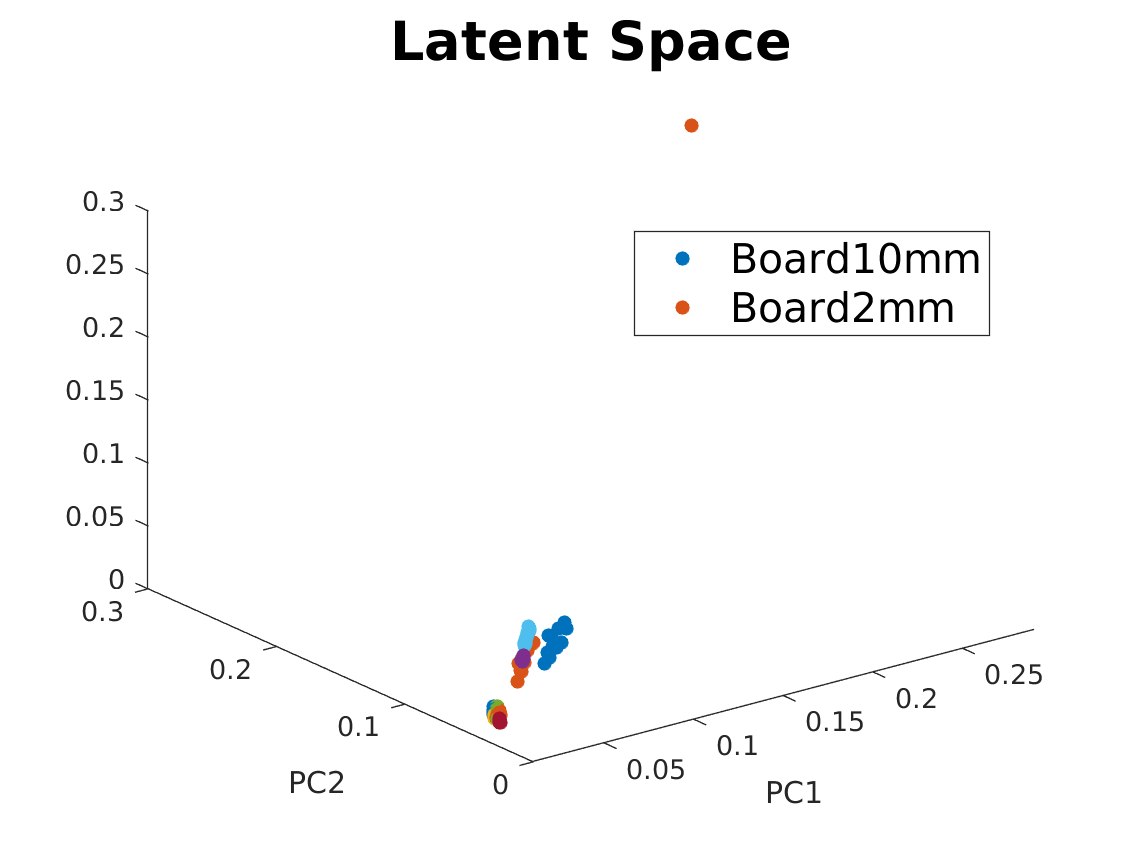

if exist('fc2', 'var')
    coeffs = fc2.fbasis_coeffs;
    
    [~, r2, r3] = size(coeffs);
    coeffs_cov = zeros(r2, r2, r3);
    for i3=1:r3
        coeffs_cov(:, :, i3) = cov(coeffs(:, :, i3));
    end
    
    coeffs_cov = tensor(coeffs_cov);
    Zq = encodeTensor(coeffs_cov, T, n_cores)';
    
    clear s2labels
    
    h(7) = figure(7);
    hold on
    class_names = string(fc2.class_names).strip('both');
    gscatter3(Zq(:, 1), Zq(:, 2), Zq(:, 3), class_names);
    legend('Location', 'best', 'FontSize', 15)
end